% 5 Feb 2018

% Ex 1

syms q1 real
syms q2 real
syms q3 real
syms q4 real

syms a2 positive real
syms a3 positive real
syms a4 positive real

syms d1 positive real

joints = 'RRRR';
alpha = [pi/2, 0, 0, 0];
a=[0 a2 a3 a4];
d=[d1,0,0,0];
theta=[q1,q2,q3,q4];

table=[alpha',a',d',theta']

$$table = \left(\begin{array}{cccc} \frac{\pi }{2} & 0 & d_{1} & q_{1}\\ 0 & a_{2} & 0 & q_{2}\\ 0 & a_{3} & 0 & q_{3}\\ 0 & a_{4} & 0 & q_{4} \end{array}\right)$$


[T, A] = DHMatrix(table);
A0_1=A{1}

$$A0\_1 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & \sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & 0 & -\cos\left(q_{1}\right) & 0\\ 0 & 1 & 0 & d_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A1_2=A{2}

$$A1\_2 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0 & a_{2}\,\cos\left(q_{2}\right)\\ \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0 & a_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A2_3=A{3}

$$A2\_3 = \left(\begin{array}{cccc} \cos\left(q_{3}\right) & -\sin\left(q_{3}\right) & 0 & a_{3}\,\cos\left(q_{3}\right)\\ \sin\left(q_{3}\right) & \cos\left(q_{3}\right) & 0 & a_{3}\,\sin\left(q_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A3_4=A{4}

$$A3\_4 = \left(\begin{array}{cccc} \cos\left(q_{4}\right) & -\sin\left(q_{4}\right) & 0 & a_{4}\,\cos\left(q_{4}\right)\\ \sin\left(q_{4}\right) & \cos\left(q_{4}\right) & 0 & a_{4}\,\sin\left(q_{4}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T

$$T = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{3}\,\cos\left(q_{1}\right) & -\sigma_{1}\,\cos\left(q_{1}\right) & \sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\sigma_{2}\\ \sigma_{3}\,\sin\left(q_{1}\right) & -\sigma_{1}\,\sin\left(q_{1}\right) & -\cos\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sigma_{2}\\ \sigma_{1} & \sigma_{3} & 0 & d_{1}+a_{3}\,\sin\left(q_{2}+q_{3}\right)+a_{2}\,\sin\left(q_{2}\right)+a_{4}\,\sigma_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{2}+q_{3}+q_{4}\right)\\ \sigma_{2}=a_{3}\,\cos\left(q_{2}+q_{3}\right)+a_{2}\,\cos\left(q_{2}\right)+a_{4}\,\sigma_{3}\\ \sigma_{3}=\cos\left(q_{2}+q_{3}+q_{4}\right) \end{array}$$

% Ex 2

%A
f_r = simplify(get_f_r(T))

$$f\_r = \begin{array}{l} \left(\begin{array}{c} \cos\left(q_{1}\right)\,\sigma_{1}\\ \sin\left(q_{1}\right)\,\sigma_{1}\\ d_{1}+a_{3}\,\sin\left(q_{2}+q_{3}\right)+a_{2}\,\sin\left(q_{2}\right)+a_{4}\,\sin\left(q_{2}+q_{3}+q_{4}\right)\\ q_{1}+q_{2}+q_{3}+q_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{3}\,\cos\left(q_{2}+q_{3}\right)+a_{2}\,\cos\left(q_{2}\right)+a_{4}\,\cos\left(q_{2}+q_{3}+q_{4}\right) \end{array}$$

[Jl, Ja] = geometric_jacobian(f_r, joints, [q1 q2 q3 q4], table)

$$Jl = \begin{array}{l} \left(\begin{array}{cccc} -\sin\left(q_{1}\right)\,\sigma_{3} & -\cos\left(q_{1}\right)\,\sigma_{1} & -\cos\left(q_{1}\right)\,\sigma_{2} & -a_{4}\,\sin\left(q_{2}+q_{3}+q_{4}\right)\,\cos\left(q_{1}\right)\\ \cos\left(q_{1}\right)\,\sigma_{3} & -\sin\left(q_{1}\right)\,\sigma_{1} & -\sin\left(q_{1}\right)\,\sigma_{2} & -a_{4}\,\sin\left(q_{2}+q_{3}+q_{4}\right)\,\sin\left(q_{1}\right)\\ 0 & \sigma_{3} & a_{3}\,\cos\left(q_{2}+q_{3}\right)+\sigma_{4} & \sigma_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{3}\,\sin\left(q_{2}+q_{3}\right)+a_{2}\,\sin\left(q_{2}\right)+a_{4}\,\sin\left(q_{2}+q_{3}+q_{4}\right)\\ \sigma_{2}=a_{3}\,\sin\left(q_{2}+q_{3}\right)+a_{4}\,\sin\left(q_{2}+q_{3}+q_{4}\right)\\ \sigma_{3}=a_{3}\,\cos\left(q_{2}+q_{3}\right)+a_{2}\,\cos\left(q_{2}\right)+\sigma_{4}\\ \sigma_{4}=a_{4}\,\cos\left(q_{2}+q_{3}+q_{4}\right) \end{array}$$

$$Ja = \left(\begin{array}{cccc} 0 & \sin\left(q_{1}\right) & \sin\left(q_{1}\right) & \sin\left(q_{1}\right)\\ 0 & -\cos\left(q_{1}\right) & -\cos\left(q_{1}\right) & -\cos\left(q_{1}\right)\\ 1 & 0 & 0 & 0 \end{array}\right)$$

rank(Jl)

ans = 3

 tvals = [1 2 2.5 4];
 qvals = [45 90 -45 45];

coeffs = fliplr(splines(tvals, qvals))

$$A = \left(\begin{array}{cc} 2\,t_{3}-2\,t_{1} & t_{2}-t_{1}\\ t_{4}-t_{3} & 2\,t_{4}-2\,t_{2} \end{array}\right)$$

$$b = \left(\begin{array}{c} -\frac{\left(3\,q_{1}-3\,q_{2}\right)\,\left(t_{2}-t_{3}\right)}{t_{1}-t_{2}}-\frac{\left(3\,q_{2}-3\,q_{3}\right)\,\left(t_{1}-t_{2}\right)}{t_{2}-t_{3}}\\ -\frac{\left(3\,q_{2}-3\,q_{3}\right)\,\left(t_{3}-t_{4}\right)}{t_{2}-t_{3}}-\frac{\left(3\,q_{3}-3\,q_{4}\right)\,\left(t_{2}-t_{3}\right)}{t_{3}-t_{4}} \end{array}\right)$$

Symbolic Cubic 1 parameters:


$$a = \left(\begin{array}{c} q_{1}\\ 0\\ 3\,q_{2}-3\,q_{1}+v_{2}\,\left(t_{1}-t_{2}\right)\\ 2\,q_{1}-2\,q_{2}-v_{2}\,\left(t_{1}-t_{2}\right) \end{array}\right)$$

Symbolic Cubic 2 parameters:


$$a = \left(\begin{array}{c} q_{2}\\ -v_{2}\,\left(t_{2}-t_{3}\right)\\ 3\,q_{3}-3\,q_{2}+3\,v_{2}\,\left(t_{2}-t_{3}\right)-\left(t_{2}-t_{3}\right)\,\left(v_{2}-v_{3}\right)\\ 2\,q_{2}-2\,q_{3}-2\,v_{2}\,\left(t_{2}-t_{3}\right)+\left(t_{2}-t_{3}\right)\,\left(v_{2}-v_{3}\right) \end{array}\right)$$

Symbolic Cubic 3 parameters:


$$a = \left(\begin{array}{c} q_{3}\\ -v_{3}\,\left(t_{3}-t_{4}\right)\\ 3\,q_{4}-3\,q_{3}+2\,v_{3}\,\left(t_{3}-t_{4}\right)\\ 2\,q_{3}-2\,q_{4}-v_{3}\,\left(t_{3}-t_{4}\right) \end{array}\right)$$

coeffs =  -265.7143  310.7143         0   45.0000
   74.4643 -121.6071  -87.8571   90.0000
 -503.0357  916.0714 -323.0357  -45.0000



syms tau t real;
pols = cell(3);
N = 4

N = 4

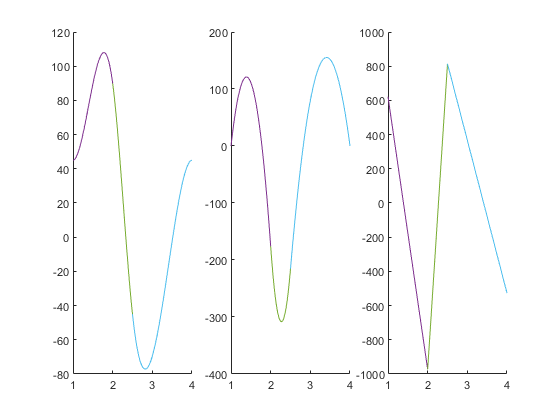


% Plot Joint Values
subplot(1, 3, 1);
hold on
for i = 1:N-1
    taut = (t - tvals(i)) / (tvals(i+1) - tvals(i));
    pol = poly2sym(coeffs(i, :), tau);
    pol = subs(pol, tau, taut);
    pols{i} = pol;
    fplot(pol, tvals(i:i+1));
end
hold off

% Plot Velocity
subplot(1, 3, 2);
hold on
vels = cell(3);
for i = 1:N-1
    vel = diff(pols{i}, t);
    vels{i} = vel;
    fplot(vel, tvals(i:i+1));
end
hold off


% Plot Acceleration
subplot(1, 3, 3);
hold on
accs = cell(3);
for i = 1:N-1
    acc = diff(vels{i}, t);
    accs{i} = pol;
    fplot(acc, tvals(i:i+1));
end
hold off